# Esercizio di Robotica Mobile

## Blocco Mobile Robot

Per prima cosa, occorre definire il modello del robot che verrà utilizzato. Nel contesto di questo progetto, si è optato per il modello uniciclo:

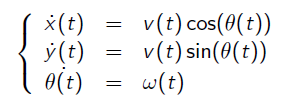

In questa sezione, si procede alla definizione del parametro strutturale chiave, che è il diametro del robot. I segnali di comando, invece, verranno determinati nella sezione dedicata al blocco del *Controller*.

clear; close all; clc;

% MOBILE ROBOT
diametro = 5;

## Blocco Environment

In questa fase si progetta l'ambiente prestabilito in cui il robot si potrà muovere. Scorrere in basso per poterlo vedere.

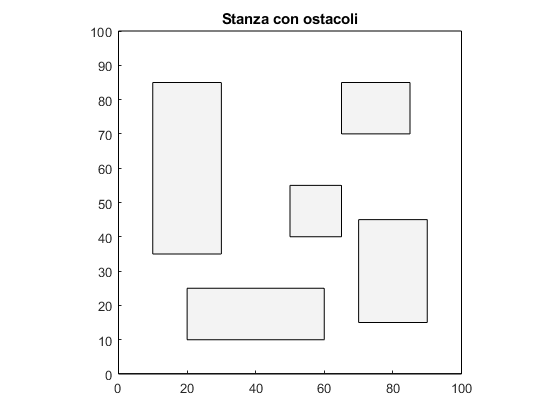

% ENVIRONMENT

% OSTACOLI
% ostacolo i = [sw; se; nw; ne]
% stanza
ostacoli = [0 0;100 0;0 100;100 100;];
% ostacolo 1 nella stanza
ostacoli = [ostacoli;10 35;30 35; 10 85;30 85];
% ostacolo 2 nella stanza
ostacoli = [ostacoli;20 10;60 10; 20 25;60 25];
% ostacolo 3 nella stanza
ostacoli = [ostacoli;50 40;65 40; 50 55;65 55];
% ostacolo 4 nella stanza
ostacoli = [ostacoli;70 15;90 15; 70 45;90 45];
% ostacolo 5 nella stanza
ostacoli = [ostacoli;65 70;85 70; 65 85;85 85];

% Plot stanza con ostacoli
figure(1); axis('equal'); axis([0 100 0 100]); title('Stanza con ostacoli')
rectangle('Position', [ostacoli(1,1) ostacoli(1,2) ...
    ostacoli(4,1)-ostacoli(1,1) ostacoli(4,2)-ostacoli(1,2)]);
for i=5:4:length(ostacoli)
    rectangle('Position', [ostacoli(i,1) ostacoli(i,2) ...
        ostacoli(i+3,1)-ostacoli(i,1) ostacoli(i+3,2)-ostacoli(i,2)], ...
        'FaceColor', '#f3f3f3');
end

% La seguente variabile costituisce il vettore dei punti che
% formano i bordi degli ostacoli
[stanza]=Utilita.Costruisci_Stanza(ostacoli);

#### Scelta di posizione iniziale, goal ed orientamento

Seguire le istruzioni presenti nella command window per procedere.

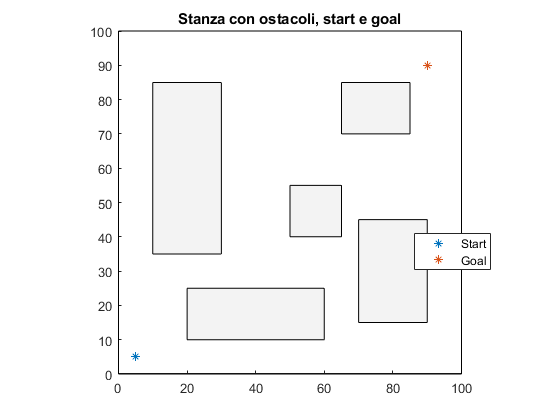

prompt1 = "Inserire i valori del punto di partenza 'SP=[x,y]', del " + ...
    "goal 'G=[x,y]',\ndell'orientamento finale 'thetaG=x' (espresso " + ...
    "in radianti) e premere \nINVIO:\n > SP = ";
SP = input(prompt1);
G = input(" > G = ");
thetaG = input(" > thetaG = ");

% Plot stanza con ostacoli, start e goal
figure(1); hold on;
title('Stanza con ostacoli, start e goal');
plot(SP(1),SP(2),'*'); plot(G(1),G(2),'*'); 
legend('Start','Goal','Location','best');

## Blocco Planner

A questo punto si conoscono sia l'ambiente che il task, quindi si può procedere con la progettazzione delle traiettorie.

Per scegliere quale planner utilizzare, seguire le istruzioni presenti nella command window.

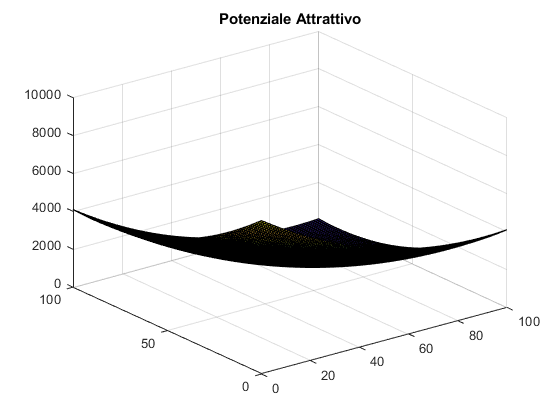

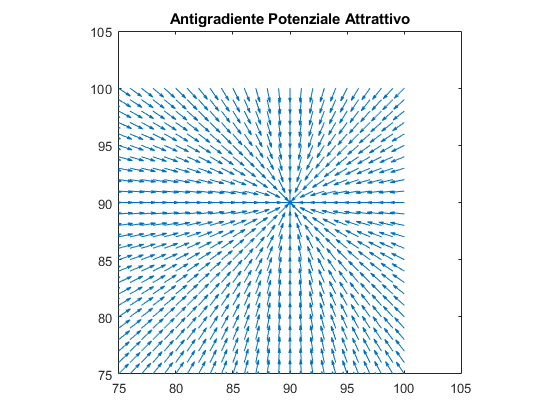

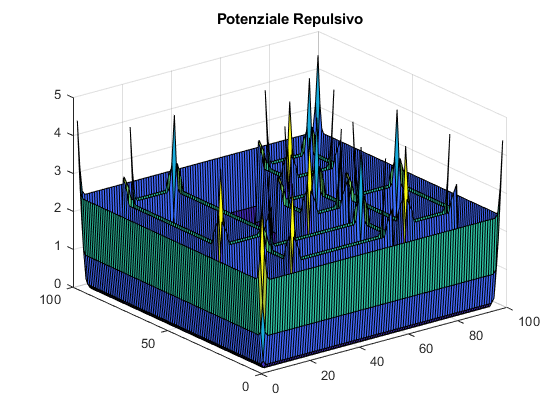

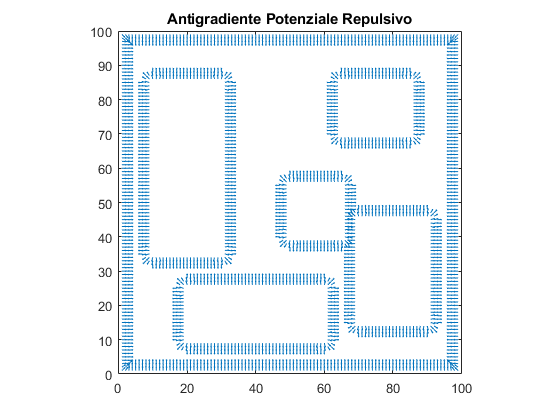

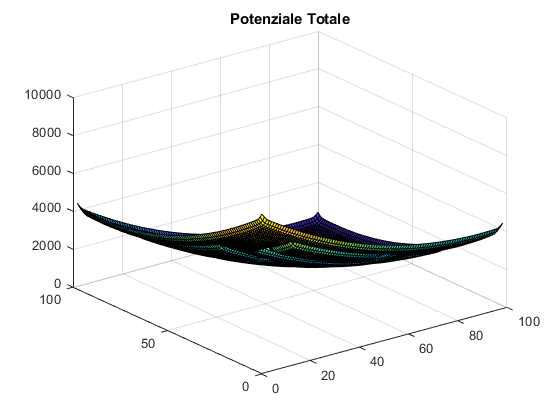

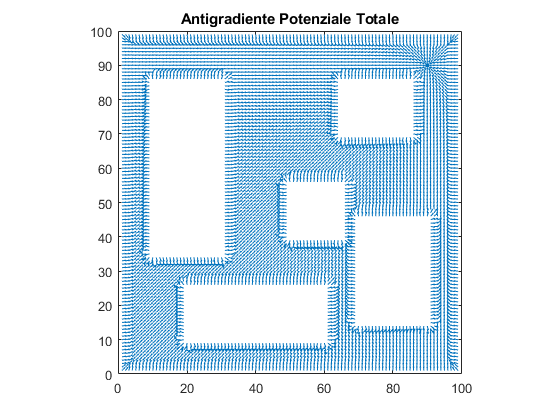

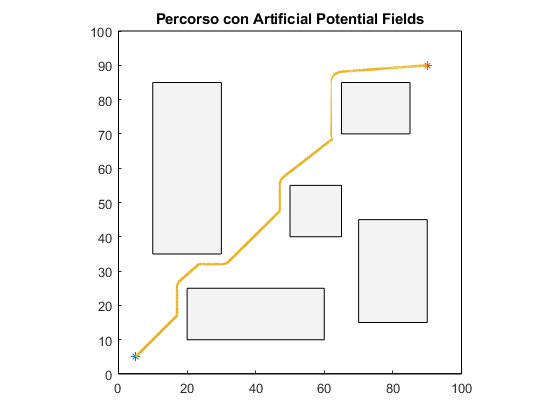

% PLANNER

clc; prompt2 = "Inserire il numero relativo alla tecnica che si vuole " + ...
    "utilizzare e \npremere INVIO:\n 1) Artificial Potential Fields\n " + ...
    "2) Discrete Potential Fields\n 3) Voronoi Diagrams\n 4) " + ...
    "Visibility Graphs \n> ";
scelta_planner = input(prompt2);

switch scelta_planner
    case 1
        [path]=Planners.Artificial_Potential_Fields(SP,G,stanza,ostacoli);
    case 2
        [path]=Planners.Discrete_Potential_Fields(SP,G,ostacoli);
    case 3
        [path]=Planners.Voronoi_Diagrams(SP,G,stanza,ostacoli);
    case 4
        [path]=Planners.Visibility_Graphs(SP,G,ostacoli);
end

## Blocco Controller

### Trajectory Tracking

In questa sezione ci si occupa di progettare una legge di controllo per inseguire la traiettoria ottenuta al punto precedente.

Per scegliere quale legge di controllo utilizzare, seguire le istruzioni presenti nella command window.

% CONTROLLER - Trajectory Tracking

% Definizione della traiettoria di riferimento
P=polyfit(path(:,1),path(:,2),5);
x_star=@(t)(t);
y_star=@(t)(P(1)*t.^5 + P(2)*t.^4 + P(3)*t.^3 + P(4)*t.^2 ...
    + P(5)*t + P(6));
   
xd_star=@(t)(ones(size(t)));
yd_star=@(t)(5*P(1)*t.^4 + 4*P(2)*t.^3 + 3*P(3)*t.^2 + 2*P(4)*t + P(5));
theta_star=@(t)(atan2(yd_star(t),xd_star(t)));
   
xdd_star=@(t)(zeros(size(t)));
ydd_star=@(t)(20*P(1)*t.^3 + 12*P(2)*t.^2 + 6*P(3)*t + 2*P(4));

x0=SP(1)+2; y0=SP(2)+2; theta0=thetaG+pi/2;

clc; prompt3 = "Inserire il numero relativo alla legge di controllo" + ...
    " che si vuole \nutilizzare e premere INVIO:\n 1) Controllo " + ...
    "Lineare\n 2) Controllo Non Lineare\n 3) Input-Output Linearization\n> ";
scelta_legge = input(prompt3);

switch scelta_legge
    case 1
        % Controllo lineare
        a=0.2;
        if scelta_planner==4
            a=1;
        end
        delta=0.99;
        f_robot=@(t,X)(Controllers.robot_control_lin(t,X, ...
            x_star,y_star,theta_star, ...
            xd_star,yd_star,xdd_star,ydd_star,a,delta));
    case 2
        % Controllo non lineare
        k1=@(vs,ws)(ones(size(vs)));
        k3=@(vs,ws)(ones(size(vs)));
        k2=0.03;
        if scelta_planner==4
            k2=0.001;
        end
        f_robot=@(t,X)(Controllers.robot_control_NL(t,X, ...
            x_star,y_star,theta_star, ...
            xd_star,yd_star, ...
            xdd_star,ydd_star,k1,k2,k3));
    case 3
        % Feedback linearization
        k1=0.2;
        k2=0.2;
        b=0.5;
        f_robot=@(t,X)(Controllers.robot_control_FL(t,X, ...
            x_star,y_star, ...
            xd_star,yd_star,k1,k2,b));
end

Tsim=path(length(path))-1;

[t,evolution]=ode45(f_robot,[1,Tsim],[x0;y0;theta0]);

x=evolution(:,1);
y=evolution(:,2);
theta=(evolution(:,3));

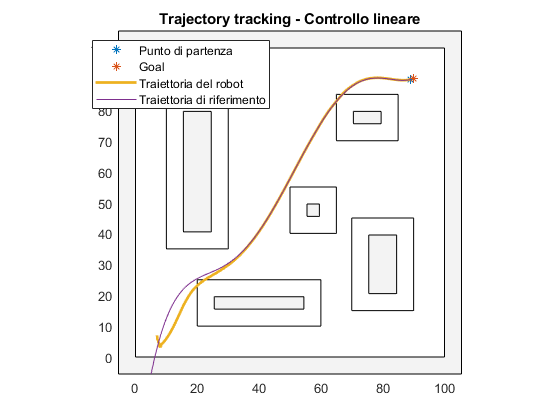

% Plot della stanza con gli ostacoli "ingrassati" di 5 (raggio del robot) +
% il 10% del raggio
r = diametro + diametro*0.10;
Utilita.plot_ostacoli_ingrassati(ostacoli,x0,y0,G,r);

% Plot della traiettoria di riferimento e della traiettoria del robot
plot(x,y,"LineWidth",2);
plot(x_star(t),y_star(t));
switch scelta_legge
    case 1
        title('Trajectory tracking - Controllo lineare');
    case 2
        title('Trajectory tracking - Controllo non lineare');
    case 3
        title('Trajectory tracking - Feedback linearization');
end
legend('Punto di partenza','Goal','Traiettoria del robot', ...
    'Traiettoria di riferimento','Location','best'); hold off;

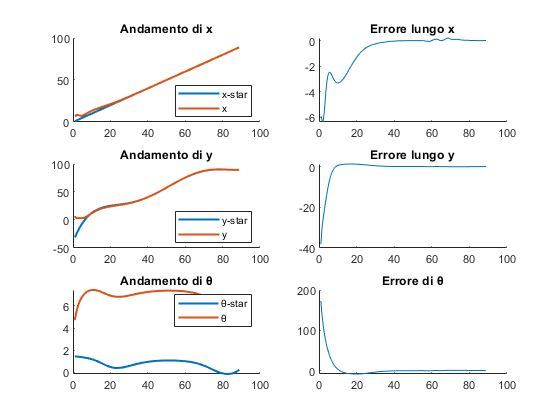

% Plot degli andamenti delle variabili
if (scelta_legge==3)
    Utilita.plot_andamenti_1(t,x,x_star,y,y_star,theta,theta_star, ...
    scelta_legge,b);
else
    Utilita.plot_andamenti_1(t,x,x_star,y,y_star,theta,theta_star, ...
    scelta_legge);
end

### Posture regulation

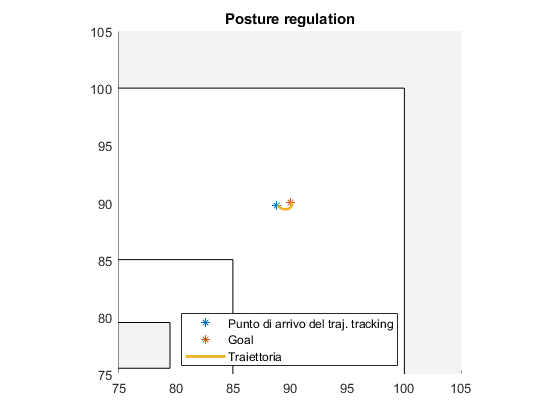

% CONTROLLER - Posture Regulation

k1=1;
k2=10;
k3=10;

f_robot=@(t,X)(Controllers.complete_posture_regulation(t,X, ...
    [G(1);G(2);thetaG],k1,k2,k3));

x0=x(length(t));
y0=y(length(t));
theta0=theta(length(t));

[t2,evolution]=ode45(f_robot,[0,100],[x0;y0;theta0]);

x1=evolution(:,1);
y1=evolution(:,2);
theta1=(evolution(:,3));

% Plot della traiettoria ottenuta
Utilita.plot_ostacoli_ingrassati(ostacoli,x0,y0,G,r);
plot(x1,y1,"LineWidth",2);
axis([G(1)-15 G(1)+15 G(2)-15 G(2)+15]);
title('Posture regulation');
legend('Punto di arrivo del traj. tracking','Goal','Traiettoria', ...
    'Location','best'); hold off;

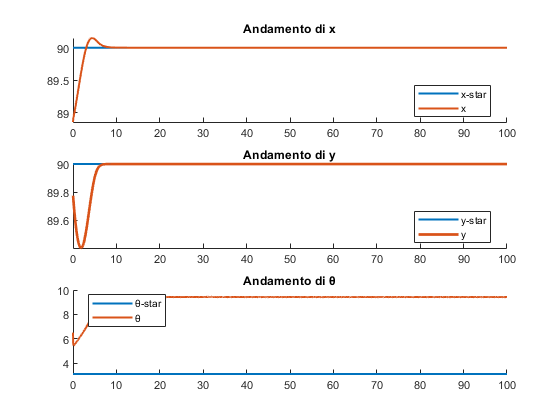

% Plot degli andamenti delle variabili
Utilita.plot_andamenti_2(t2,x1,y1,G,theta1,thetaG);